# Customizing Line Properties with Graphics Handles

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

decades = [ "[1850, 1860)";
            "[1860, 1870)";
            "[1870, 1880)";
            "[1880, 1890)";
            "[1890, 1900)";
            "[1900, 1910)";
            "[1910, 1920)";
            "[1920, 1930)";
            "[1930, 1940)";
            "[1940, 1950)";
            "[1950, 1960)";
            "[1960, 1970)";
            "[1970, 1980)";
            "[1980, 1990)";
            "[1990, 2000)";
            "[2000, 2010)";
            "[2010, 2020)"];
numEvents = [53; 72; 75; 89; 82; 84; 61; 71; 110; 93; 104; 95; 94; 93; 110; 152];
the2010s = 166;

## Task 1

p = plot(numEvents)

p =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16]
              YData: [53 72 75 89 82 84 61 71 110 93 104 95 94 93 110 152]

  Show all properties


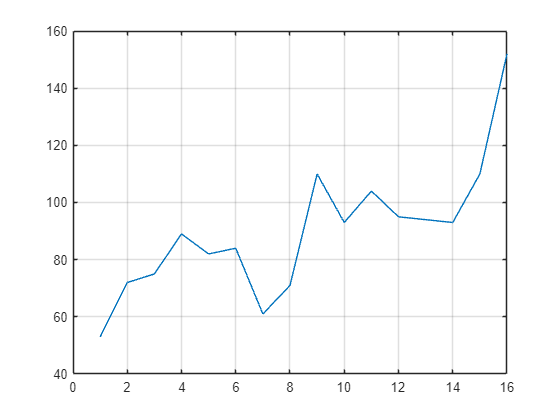

grid on

## Task 2

You can use dot notation with the property name to return the object property value.

`object.PropertyName`

lnSt = p.LineStyle

lnSt = '-'

## Task 3

You can also use dot notation to assign a value to an object property.

`object.PropertyName` `=` `newValue`

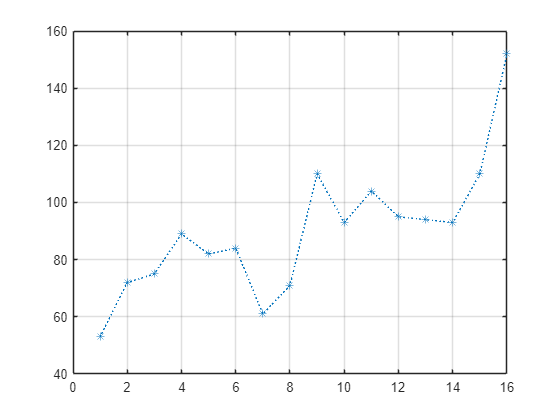

p =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: ':'
          LineWidth: 0.5000
             Marker: '*'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16]
              YData: [53 72 75 89 82 84 61 71 110 93 104 95 94 93 110 152]

  Show all properties


p.LineStyle = ":";
p.Marker = "*"

## Task 4

You can also use dot notation to update the data used in the plot. This is useful when you are creating animations or obtaining new data to add to the line plot at regular intervals (usually closer to every few minutes rather than every few decades).

To change or add points, update the `XData` and `YData` properties.  You can change one, several, or all of the values at once.

`lineObj.XData``(``k``)` `=` `newValue`  

`lineObj.XData``([``k1` `k2``])` `=` `[``x1` `x2``]`

`lineObj.XData` `=` `newValues`   

The total number of weather events for the 2010 decade is saved in the variable `the2010s`.

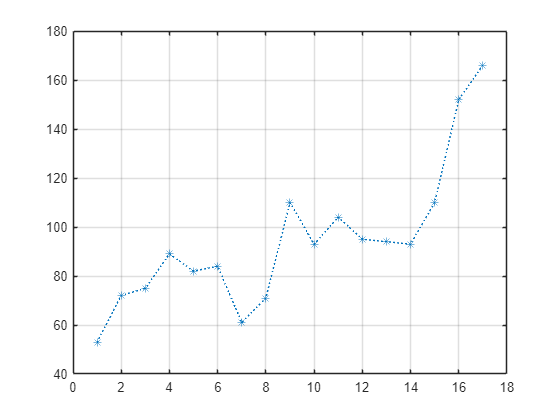

p.YData(end+1) = the2010s;

## Task 5

The `yline` function creates a horizontal line at a specified y-value.

`yline``(``yVal``,``LineSpec``,``label``)`

You can specify line style and color as line specs as a string as you can with the plot function.  Specify the label as a string.

med = median(p.YData)

med = 93

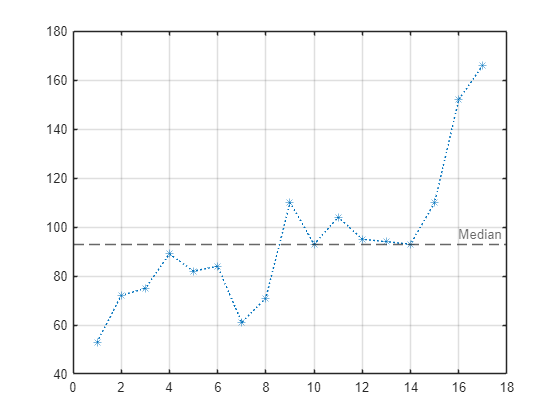

y =   ConstantLine (Median) with properties:

    InterceptAxis: 'y'
            Value: 93
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: 'Median'
      DisplayName: ''

  Show all properties


y = yline(med, "--", "Median")

## Task 6

Notice that `y` is a `ConstantLine` graphics object and has its own properties.  Some properties are the same as the `Line` object, `p`.

In addition to the properties you set (`LineStyle` and `Label`), you may recognize `Color` and `LineWidth`. 

However, there are some properties that are specific to `ConstantLine` objects like `InterceptAxis` and `Value`.  Notice that the `Value` is saved as `93`, the value of `med`, rather than the variable name.

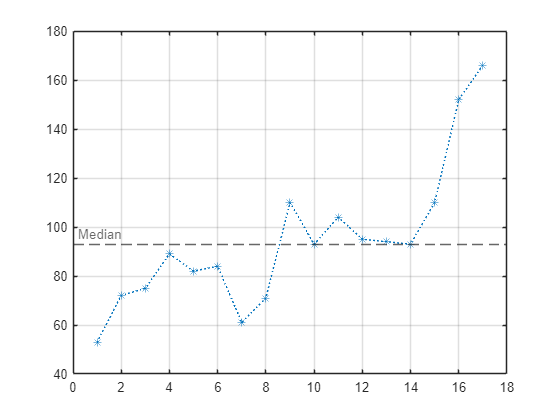

y.LabelHorizontalAlignment = "left";